# IMPORTANT: BEFORE YOU START!

Do **NOT** click on the green run button!

Execute this script by stepping section to section, read instructions and inspect results.

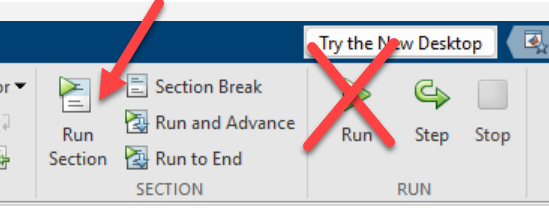

Before you start with the exercises, let's add the folder with the files and solutions required to complete each step.

addpath('./Solutions')
addpath('./Files')

# Workshop: Top-Down Design of an RF Receiver and Antenna Front-End Integration

This workshop designs a RF receiver for a 2.4GHz narrowband application using a top-down methodology. It verifies the error rate performance after the addition of impairments such as interfering signals and the integration of the antenna front-end. The example uses the `RF Budget Analyzer` App to rank the elements contributing to the noise and non-linearity budget, and the `Antenna Designer App` to design the antenna.

These are the specifications of the IEEE® 802.15.4 system and the high-level specifications of the receiver:

- Data rate = 250kbps

- OQPSK modulation with half sine pulse shaping

- Direct sequence spread spectrum with chip rate = 2Mchips/s

- Sensitivity specification = -100dBm

- Bit Error Rate (BER) specification = 1e-4

- Analog to digital converter (ADC) with 10 bits and 0dBm saturation power

Based on the above specifications, this [example](https://www.mathworks.com/help/simrf/ug/top-down-design-of-an-rf-receiver.html) shows how to use design heuristics to identify the desired Noise Figure and Gain for the RF receiver:

- **NF = 10.7dB** 

- **G = 51.5dB**

This workshop guides you through the following exercises:

**Exercise 1:**

- Starting from the receiver Gain and Noise Figure, design and analyze a cascade of RF components and integrate them in the system-level model

- Measure the corresponding Chip Error Rate (ChER) in presence of an out-of-band interfering signal

**Exercise 2:**

- Integrate a simple dipole antenna into the system-level model of the RF receiver

- Understand the impact of polarization mismatch

**Exercise 3:**

- Design a dual polarized antenna, analyze its performance using EM analysis, and integrate it in the system-level model of the RF receiver

- Design a Wilkinson combiner and integrate it together with the dual polarized antenna into the system-level model

**Exercise 4:**

- Design a 90-degrees phase shifter and implement it on a PCB together with the Wilkinson combiner

- Analyze the PCB structure using electromagnetic analysis

- Verify the system performance in terms of ChER

## Exercise 1: Design of RF Receiver

Number of steps: 7 

Expected completion time: 40 minutes

In this section, the RF receiver with the desired noise figure and gain specifications is implemented and analyzed with the RF Budget Analyzer app.

**1.1 **Launch at the command line the RF Budget Analyzer app and construct a chain of elements with the characteristics shown below:

rfBudgetAnalyzer

Specify the following system parameters representing the **desired input signal **to the receiver:

- input frequency = 2.45GHz                

- available input power = -100dBm

- bandwidth = 4MHz

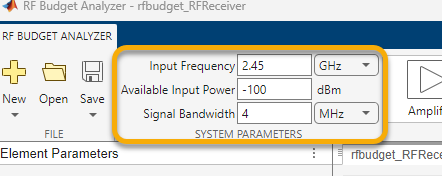

From the elements gallery, add the following components to the chain:

- S-parameters SAW filter described by means of the Touchstone file *SAWfilter.s2p*

- Amplifier (LNA) with Gain = 22dB,  Noise Figure = 7dB, OIP3 = 30dBm

- Demodulator with Local Oscillator = 2.45GHz,  Gain = -7dB, OIP2 = 55dBm, Noise Figure = 10dB

- Amplifier (VGA) with Gain = 40dB, Noise Figure = 14dB, OIP3 = 35dBm

The chain should look like this, with a total transducer gain of ~52dB, and noise figure of 10.5dB.

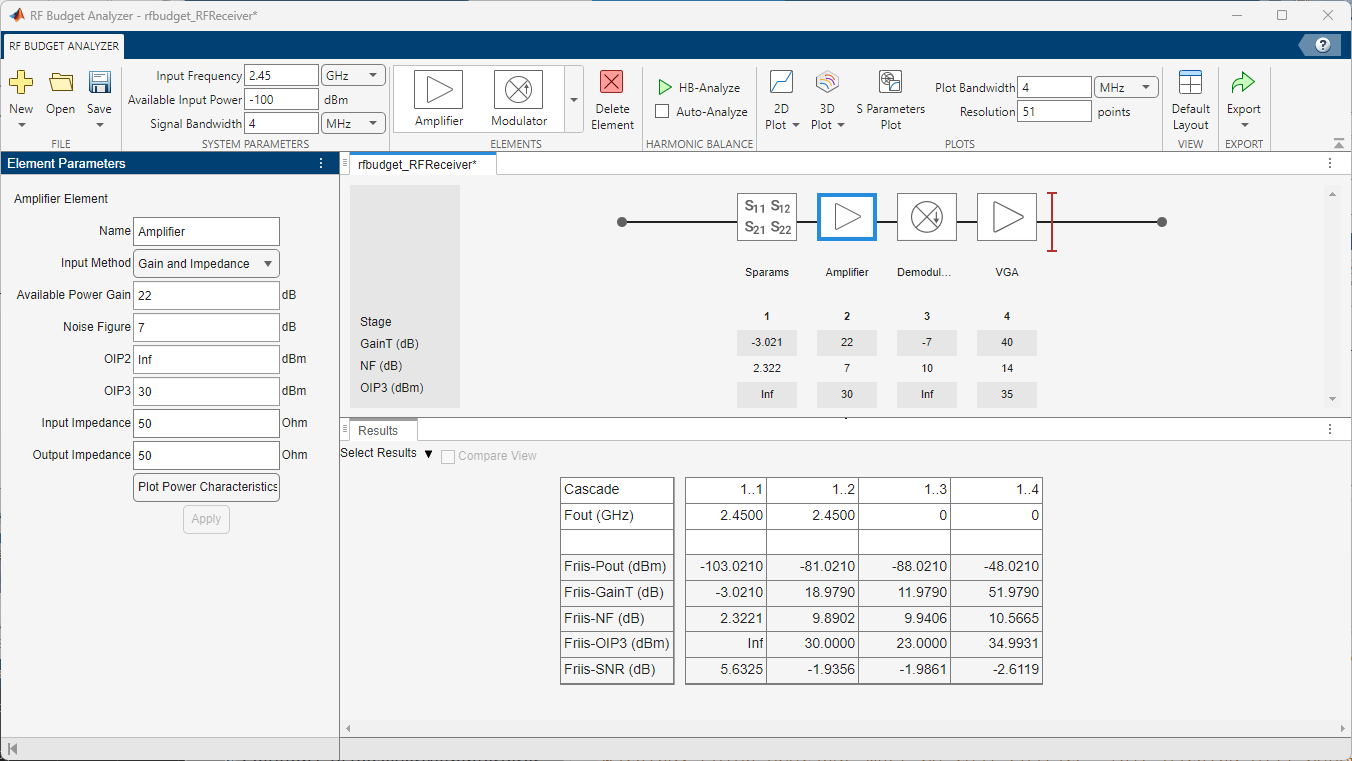

**1.2 **Compare budget results obtained with Friis equations and **Harmonic Balance** (HB) analysis and verify the noise, gain, SNR budget of the RF chain for the incoming signal.

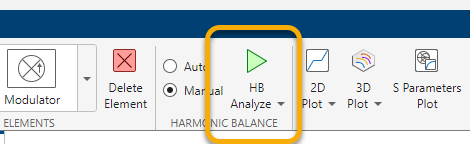

Suggestion: click on compare view in the results table.

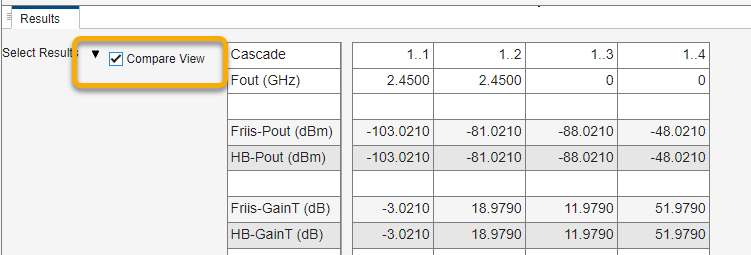

Results computed with Friis equations assume mild non-linear conditions. Harmonic Balance provides an accurate non-linear analysis of the chain based on the power of the input signal. As the power of the input signal does not excite any non-linearity, results provided by Friis and Harmonic Balance are identical.

**1.3 ** Change the system parameters to represent an **out of band interfering signal:**

- center frequency = 2.5GHz                

- available input power = -30dBm

- bandwidth = 4MHz

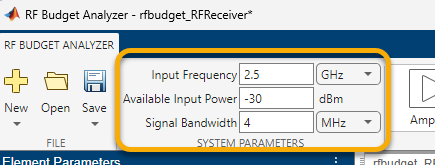

Compare budget results obtained with Friis equations and Harmonic Balance analysis and verify the noise, gain, SNR budget of the RF chain. 

*Why is the transducer gain predicted by HB 0.5dB lower than the transducer gain predicted by Friis? *

*What can you say about the impact of the interfering signal on the RF receiver operating mode and output power?*

Suggestions:

- click on compare view in the results table

- visualize power characteristics for the two amplifiers

**1.4 **From the RF Budget Analyzer app **generate an RF Blockset Circuit Envelope** receiver model. 

First, make sure that the system parameters in the RF Budget Analyzer app represent the desired input signal:

- input frequency = 2.45GHz                

- available input power = -100dB

- bandwidth = 4MHz

Export to RF Blockset from the RF Budget Analyzer app. 

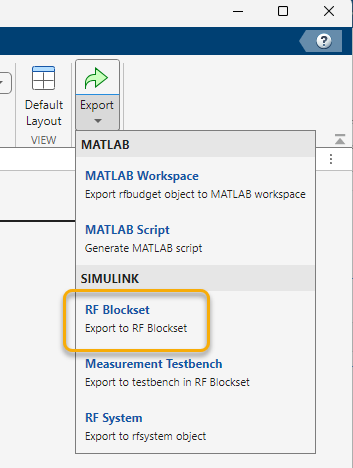

Open the available testbench `Exercise1_RFReceiverWithInterferer.slx.` 

open_system('Exercise1_RFReceiverWithInterferer.slx')

In the testbench, open the subsystem "PLACEHOLDER RF Receiver". 

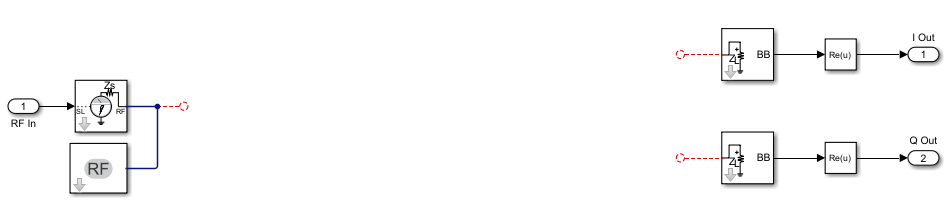

Copy the generated model from the RF Budget Analyzer app into the empty model. 

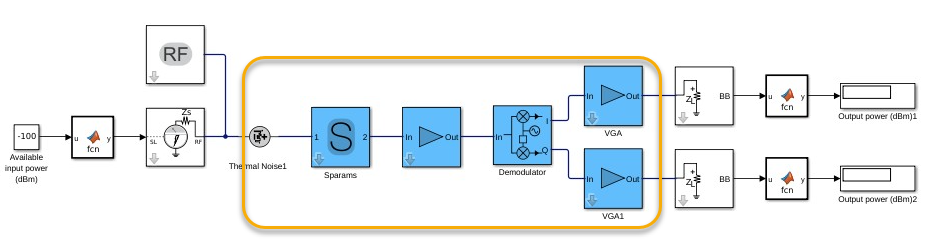

Spend a few minutes to familiarize yourself with testbench. In particular, inspect the baseband signal generation, the ADC, and the baseband receiver. 

*Why is the demodulator implemented with a quadrature (IQ) architecture?*

Suggestion: from the RF Budget Analyzer app, change the input frequency to 2.5GHz and generate a new RF Blockset model.

**1.5 **Open the mask of the **IQ demodulator block** (double click on the block), navigate to the Impairments tab and add the following impairments:

- LO to RF isolation = 105dB

- Phase noise frequency offset = [0.2,1,2,3,7]*1e6 Hz

- Phase noise levels  = [-70,-80,-95,-110,-120] dBc/Hz

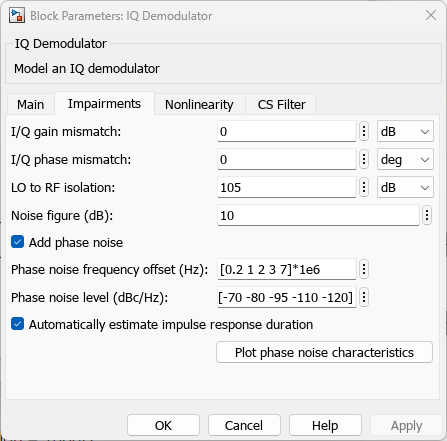

Run the model. Inspect the Chip Error Rate to be around 7%.

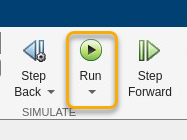

**1.6** Open the **RF input port** (Inport), and inspect its parameters.

*How many incoming signals are entering the receiver?*

Suggestion: in the MATLAB workspace verify what is the value of the variable `carrierFreqs`. As the variable is a vector, how many elements does it have?

Suggestion: click on the help button of the input port block. To learn more about how to use this block and the outport block, read the section "algorithms".

**1.7** Inspect the **spectrum of the receiver output signal** and verify the ChER in the following scenarios:

- Interfering signal power = -30dBm with DC offset correction (image on the left below)

- Interfering signal power = -200dBm, without DC offset correction (image on the right below)

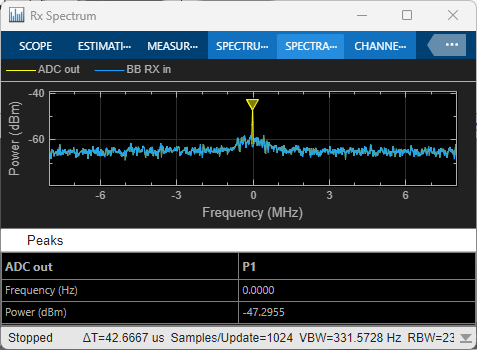 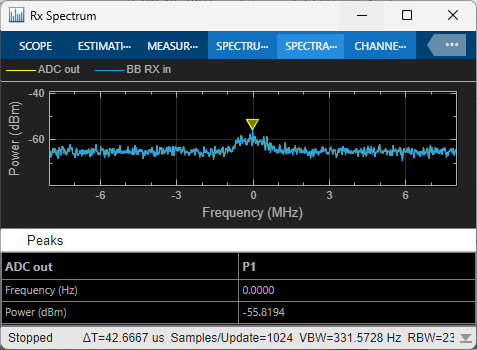

*What is the cause of the residual DC offset?*

Suggestion: to enable and disable the DC offset correction toggle the manual switch labeled "SW".

**Solution **

Execute the command below to visualize the RF receiver chain in the **RF Budget Analyzer** app.

rfBudgetAnalyzer('rfbudget_RFReceiver.mat') 

The interfering signal has higher power than the desired signal, and it is entering the saturation region of the VGA. Although the interfering signal is centered around a different frequency, saturation effects will impact also the desired signal and will ultimately result into higher ChER.

This can be visualized by plotting the power characteristic of the VGA amplifier either in the budget app or in the block mask.

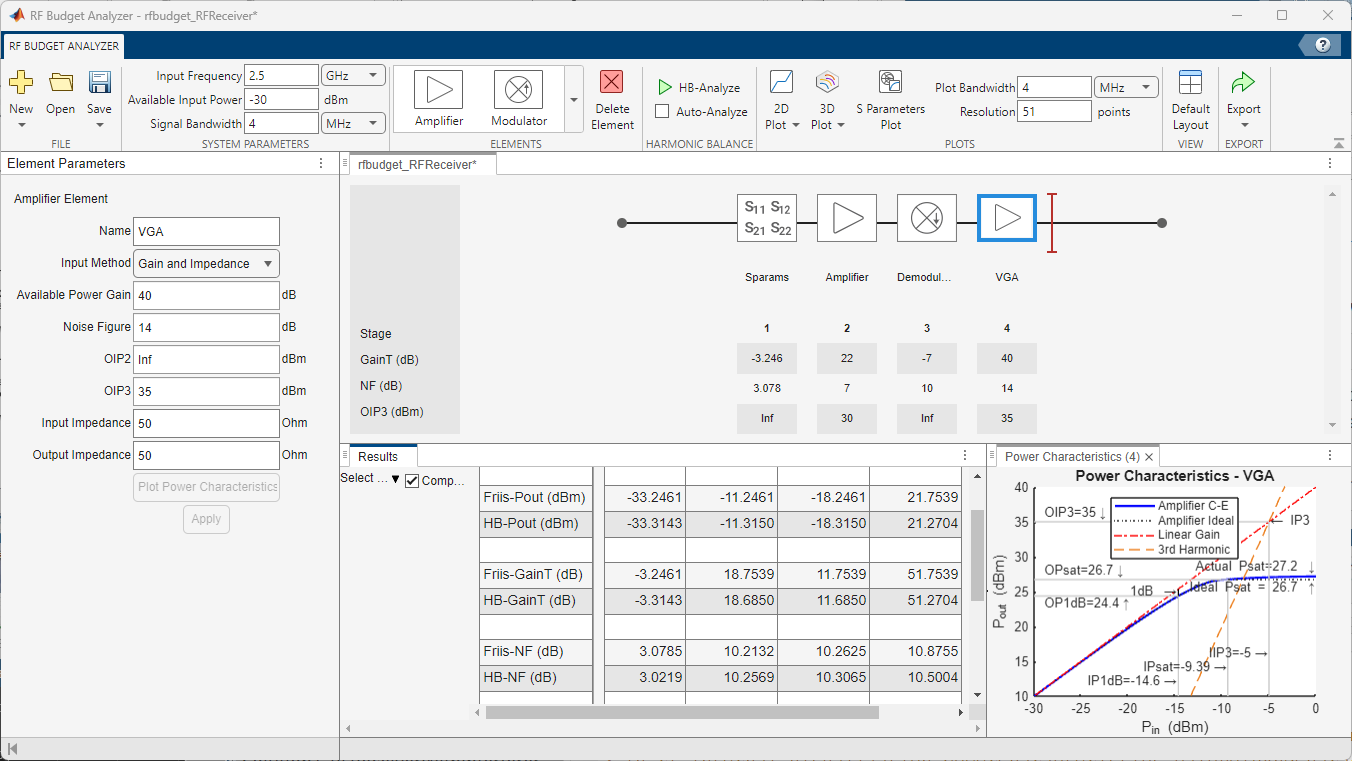

Open the model where the RF receiver has been integrated:

open_system('Solution1_RFReceiverWithInterferer.slx');

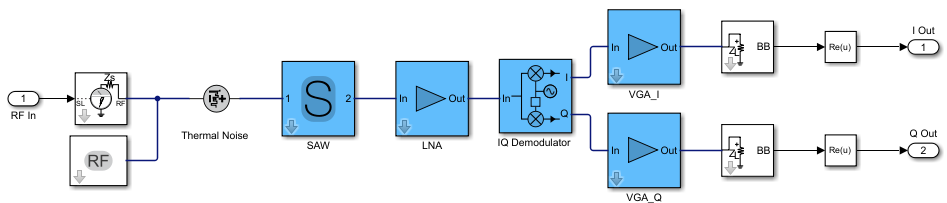

As the receiver implements a direct conversion architecture (the LO frequency is the same as the input frequency), a quadrature demodulator is required to recover the complex modulated signal.

Two signals are entering the receiver: the desired signal centered at 2.45GHz, and a high power interfering signal at 2.5GHz.

The interfering signal is exciting the non-linearity of the demodulator specified by means of IP2. In absence of a high-power signal, the residual DC offset is caused by finite LO to RF isolation. 

Extra: use the RF budget analysis of the chain to inspect the S-parameters of the cascade, and verify the phase angle of the last stage. Open the baseband receiver model, and see how this angle has been used to align the received constellation.

**Exercise outcome and summary**

In this first exercise, you learned how to analyze the RF budget of a receiver starting from high-level specifications and generating a model for system-level integration. You practiced multi-carrier simulation with interfering signals. You used analysis and simulation to cross-verify results and gain confidence in your design.

Close all figures, clear the variables in the workspace, and close the models.

close all;
clear all;
bdclose all;
clc;

## Exercise 2: Integration of RF Receiver Antenna 

Number of steps: 3

Expected completion time: 20 minutes

In this exercise, you integrate a simple dipole antenna in the RF receiver and experiment with changing the polarization of the incoming signals.

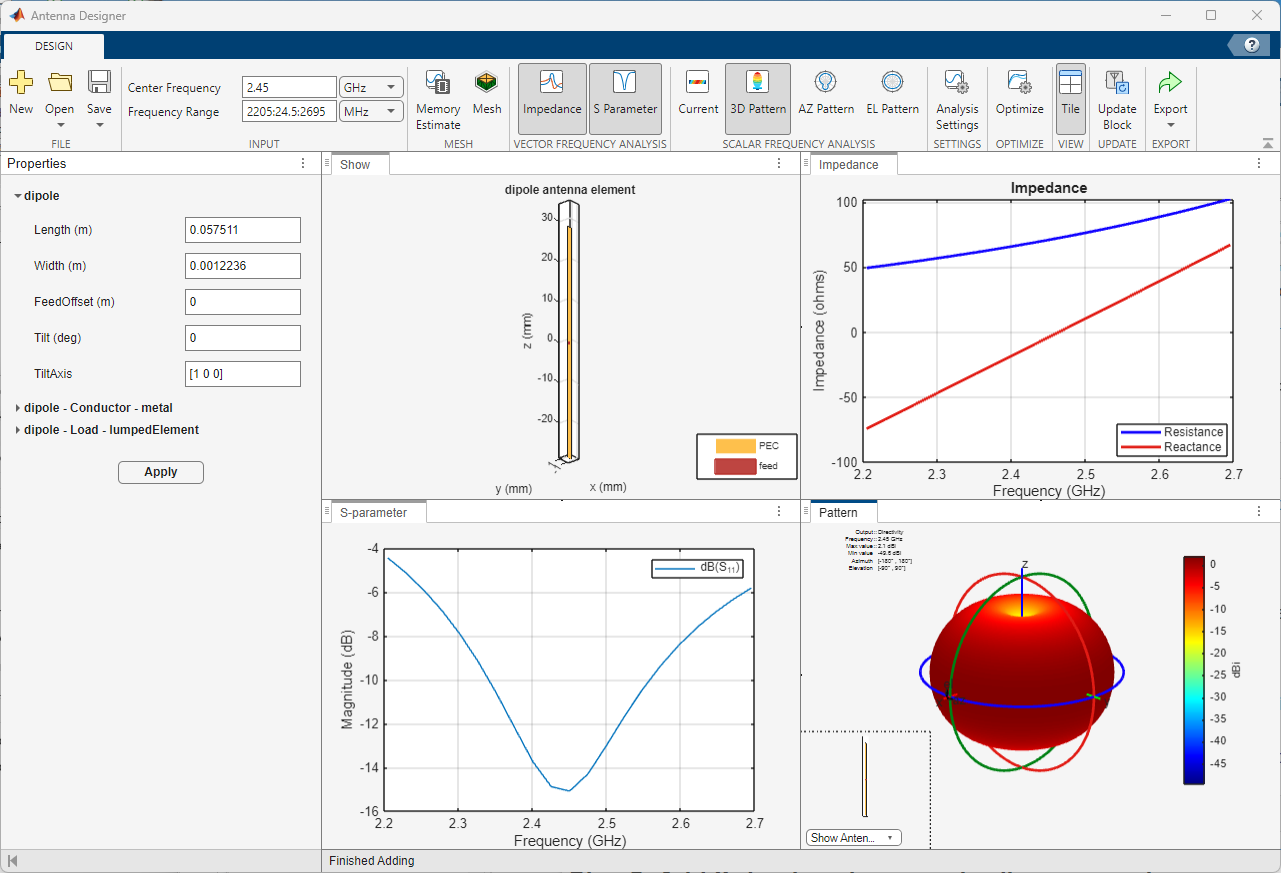

**2.1 **Open the Simulink testbench `Exercise2_RFReceiverWithAntenna`, and **open the RF receiver subsystem**. Notice that the input port is missing.

open_system('Exercise2_RFReceiverWithAntenna.slx')

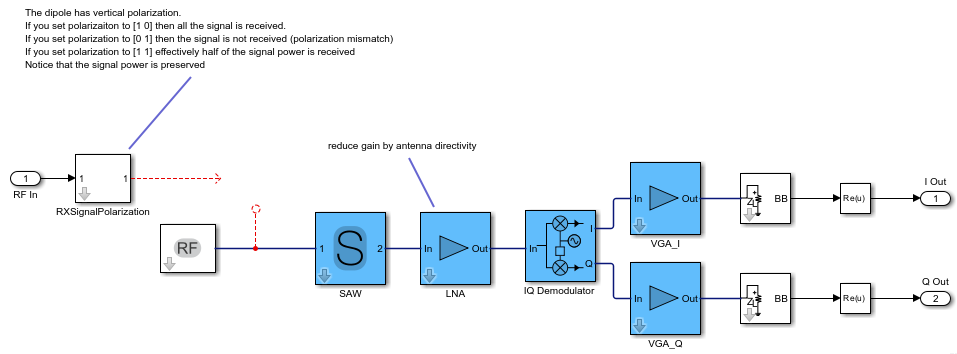

**2.2** Insert an **antenna block from the RF Blockset Circuit Envelope library**. You can either open the Simulink library browser, or simply type "antenna" in the Simulink canvas. 

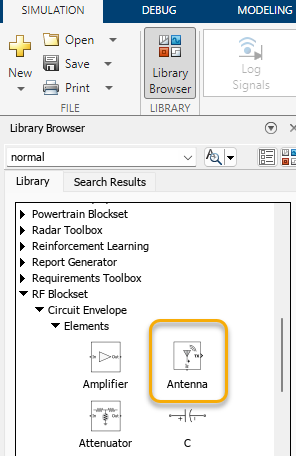

Open the mask of the antenna block (double click) and configure it as following:

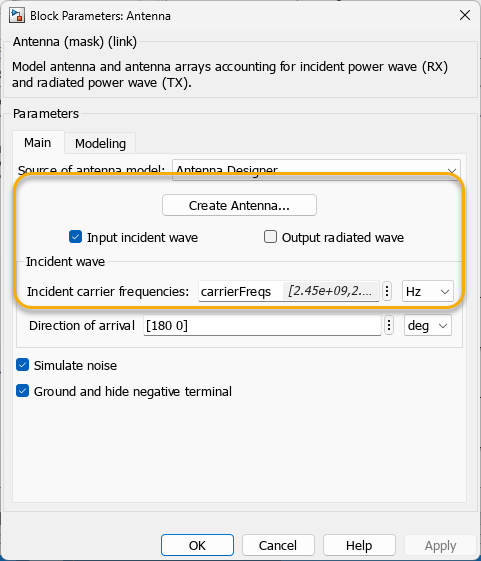

- the antenna should operate in receiving mode

- the incident carrier frequencies should be set by the variable `carrierFreqs` defined in the workspace (make sure that you change the units to Hz)

- set the source of the antenna model to be `Antenna Designer` and click on the button `Create Antenna` to open the Antenna Designer app

In the Antenna designer app, design a dipole antenna at the operating input frequency:

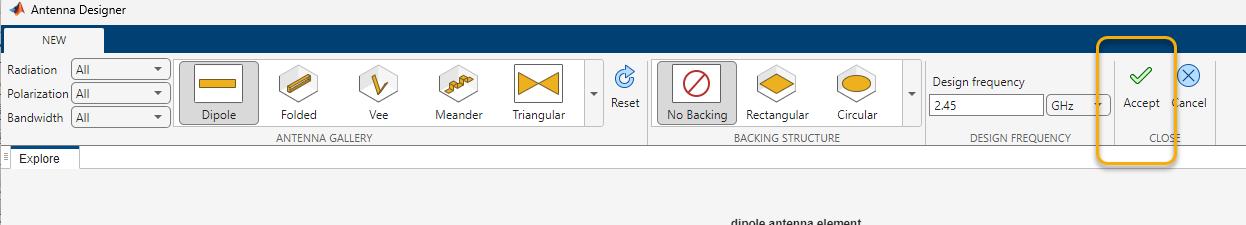

Analyze the antenna **S-parameters **and** far-field radiation pattern** as shown in the image at the beginning of the second exercise. 

Click on `Update Block` and return to the Simulink testbench.

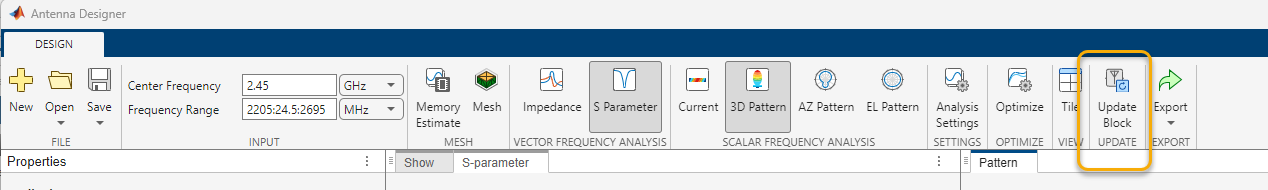

The antenna block is now fully configured.

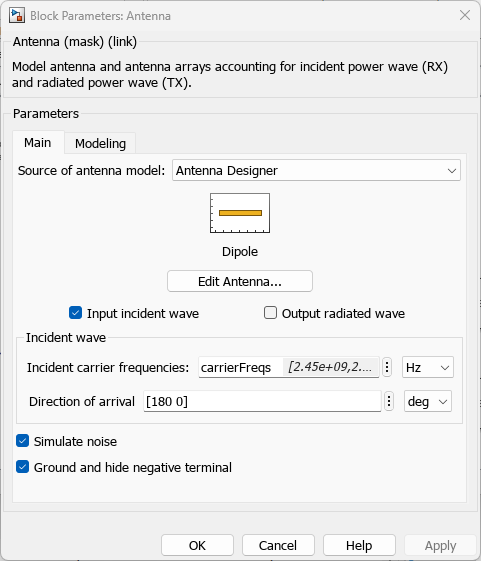

Connect the antenna block to the RF Receiver and run the simulation. 

The ChER should be around 5%.

**2.3** Open the mask parameters of the subsystem `RXSignalPolarization`, and verify the spectrum of the output signal and ChER in the following scenarios:

- Polarization Interferer = [1 0], without DC offset removal (results in the left image below)

- Polarization Interferer = [0 1], without DC offset removal (results in the right image below)

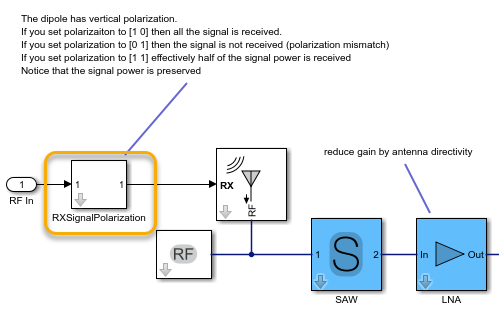

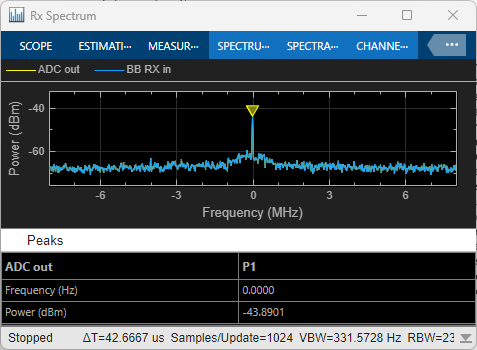 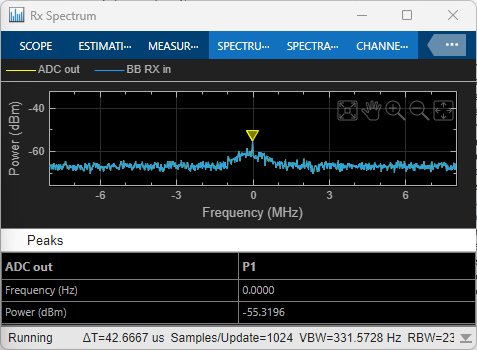

*Why is the ChER still acceptable even without DC offset correction, when the polarization of the interfering signal lies entirely on the horizontal plane?*

**Solution **

Open the resulting integrated model:

open_system('Solution2_RFReceiverWithAntenna.slx')

The dipole is a linearly polarized antenna along the vertical plane, hence incoming signals with horizontal polarization are not received.

Extra: you can verify the updated budget including the antenna block. Notice that to maintain the output power consistent with the initial budget, the amplifier gain was reduced by 2dB, the same amount as the antenna directivity gain.

rfBudgetAnalyzer('rfbudget_RFReceiverAntenna.mat') 

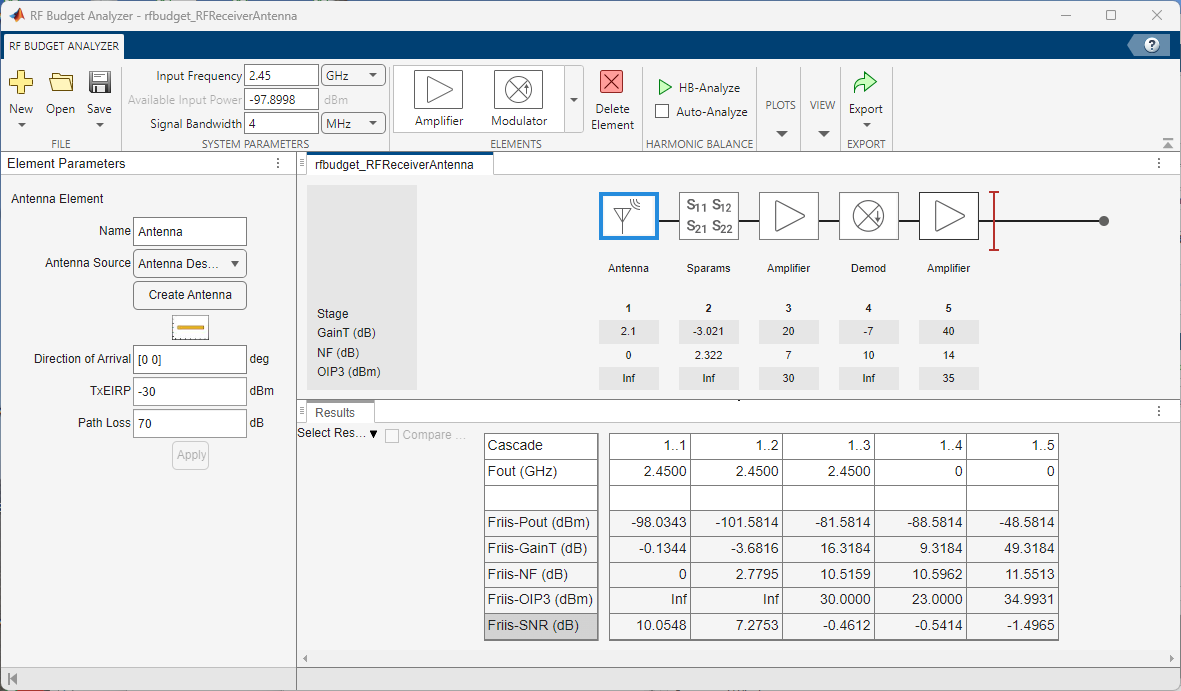

**Exercise outcome and summary**

In this second exercise, you learned how to design an antenna in MATLAB using electromagnetic analysis and integrate its characteristics in the budget analysis as well as the simulation model. You experimented with polarization mismatch, and direction of arrival.

Close all figures, clear the variables in the workspace, and close the models.

close all;
clear all;
bdclose all;

## Exercise 3: Integrate a crossed polarized dipole antenna and a Wilkinson combiner

Number of steps: 3

Expected completion time: 20 minutes

In this section you design a dipole crossed antenna and a Wilkinson combiner to merge the two polarization components of the incoming signal. Notice that the feed network of the antenna must implement a 90 degrees relative phase shift. The antenna and the Wilkinson combiner are integrated in the RF receiver.

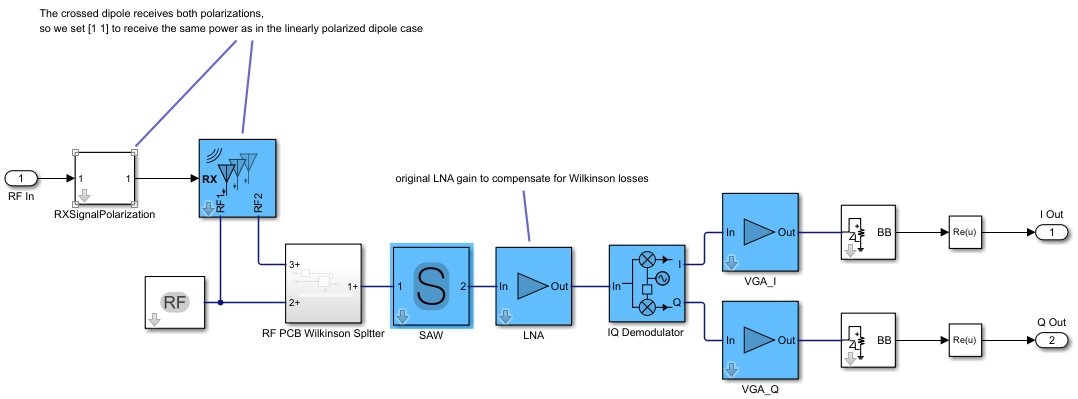

**3.1** **Design the **`dipoleCrossed` catalog element from from Antenna Toolbox to operate at the desired center frequency. Visualize the far field radiation pattern and the S-parameters.

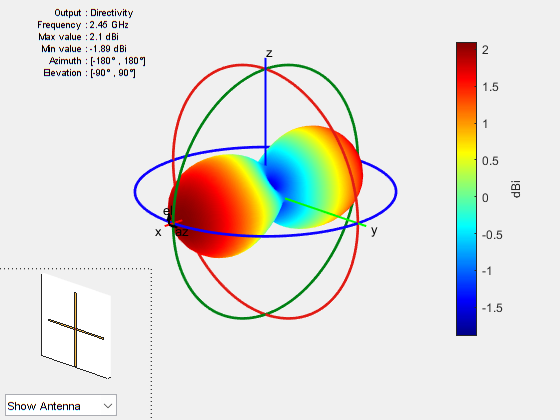

Xdipole = design(dipoleCrossed, 2.45e9);
Xdipole.Tilt = 45;
figure; show(Xdipole);
figure; pattern(Xdipole,2.45e9);

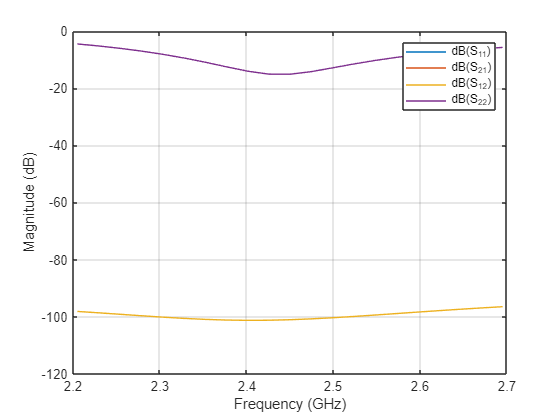

sparamXdipole = sparameters(Xdipole, (2205:24.5:2695)*1e6);
figure; rfplot(sparamXdipole);

**3.2** **Design the **`wilkinsonSplitter` catalog element from RF PCB Toolbox to operate at the desired center frequency. Analyze the S-parameters and save them as a Touchstone file. The Wilkinson splitter in this receiver will be used as a signal combiner.

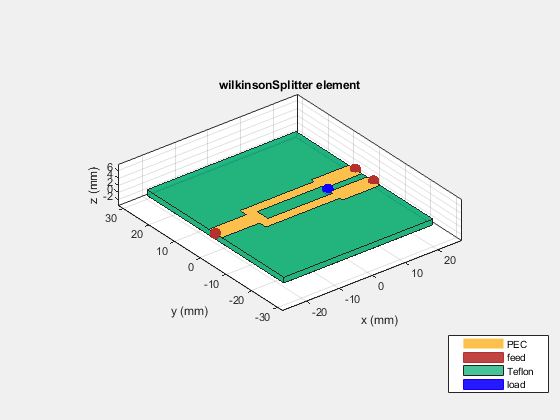

wilkCombiner=design(wilkinsonSplitter, 2.45e9);
show(wilkCombiner);

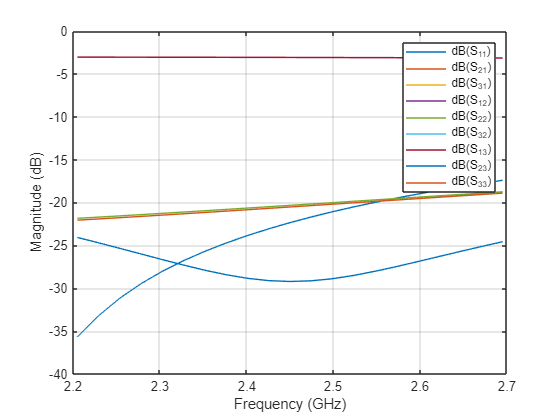

sparamWilkinson=sparameters(wilkCombiner, (2205:24.5:2695)*1e6);
figure; rfplot(sparamWilkinson);

rfwrite(sparamWilkinson,'wilkinsonSplitterSparams.s3p')

**3.3** Open the Simulink **testbench **`Exercise3_RFReceiverWithXdipole` and verify the ChER.

open_system('Exercise3_RFReceiverWithXdipole.slx')

Although we use a dual polarized antenna, because the signals are not correctly combined the ChER will be very high ~50%!

In order to properly combine the signals at the 2 antenna ports you need to include a 90 degrees phase shift on one of the combiner branches. 

*Implement the correct phase shift and verify the ChER. *

With the correct phase shift the ChER will be ~11%.

*What is the cause for the ChER degradation compared to the initial simulation when the ChER was around 7%?*

**Solution **

Open the model where the dipole crossed antenna and the Wilkinson combiner have been integrated together with a behavioral model of the phase shifter:

open_system('Solution3_RFReceiverWithXdipole.slx')

The additional insertion loss of the Wilkinson combiner contributes to additional noise and degrades the available SNR. 

Extra: you can verify the updated budget including the losses of the Wilkinson combiner. For this, you need to identify the respective 2 port S-parameters of the combiner. Notice that the SNR is now reduced compared to the original budget and the total noise figure exceeds 14 dB.

rfwrite(snp2smp(sparamWilkinson,[1 2]),'wilkinson2ports.s2p')
rfBudgetAnalyzer('rfbudget_RFReceiverXdipole.mat') 

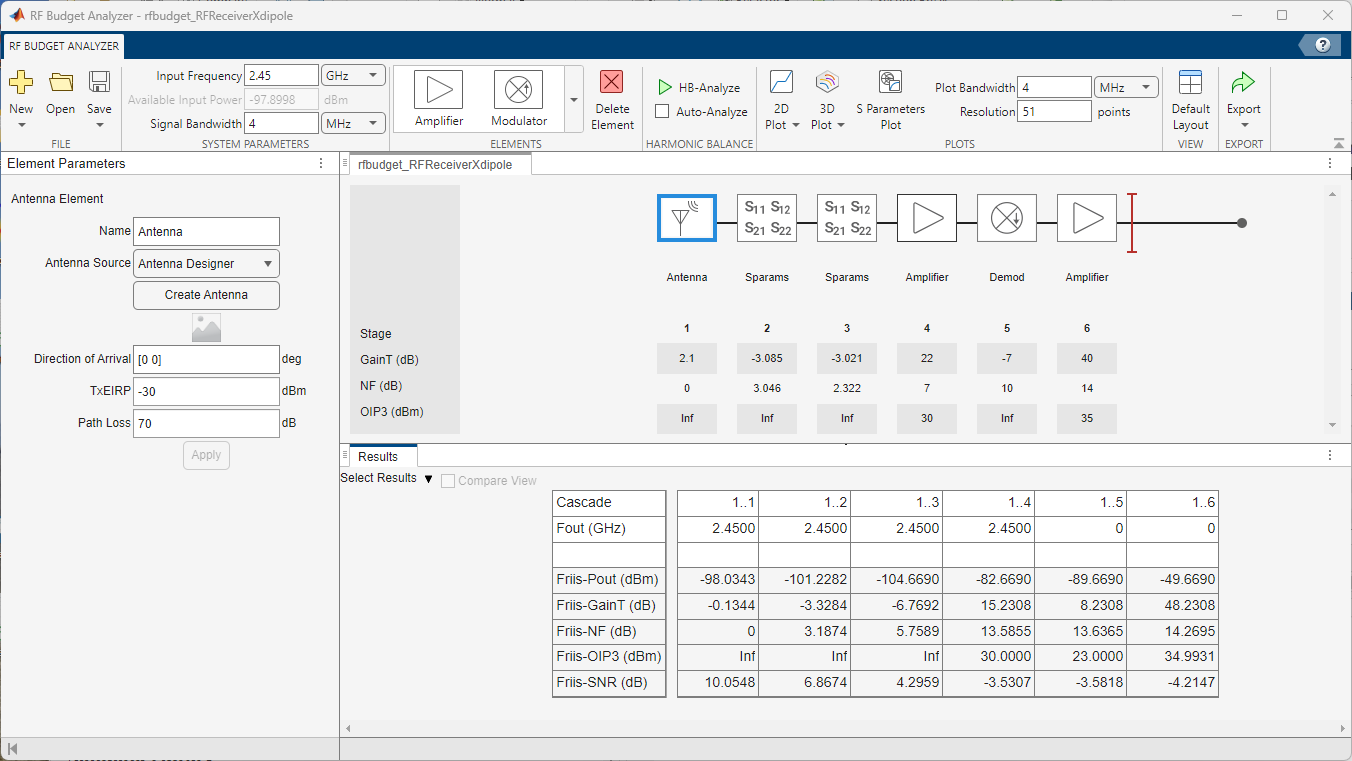

## Exercise 4: Design a Phase shifter and combine it on the PCB with the Wilkinson combiner

Number of steps: 6

Expected completion time: 20 minutes

In the previous step you determined that a 90 degrees was required to combine the two outputs from the antenna. In this step, you build the phase shifter using a distributed PCB element, and combine it on the PCB together with the Wilkinson splitter. You use EM analysis to determine the S-parameters and integrate them in the system-level model.

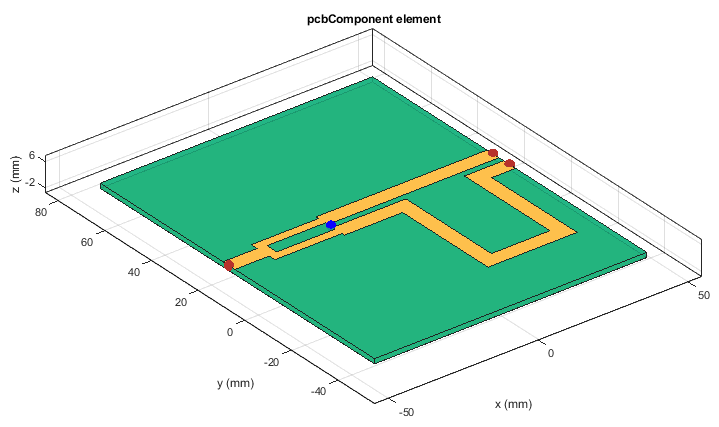

**4.1 Design the **`phaseShifter` catalog element from RF PCB Toolbox to operate at the desired center frequency. 

Compute its S-parameters using EM analysis and verify that the implemented phase shift is 90 degrees.

The phase shifter will be appended on the PCB to one of the branches of the Wilkinson combiner.

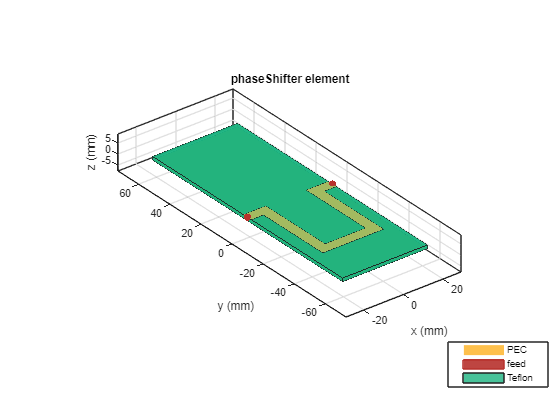

phaseShift = design(phaseShifter, 2.45e9);
figure; show(phaseShift);

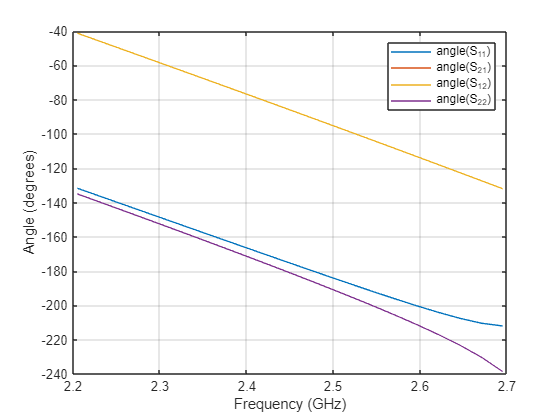

sparamPhaseShift=sparameters(phaseShift, (2205:24.5:2695)*1e6);
figure; rfplot(sparamPhaseShift,'angle');

**4.2 **To maintain a rectangular shape for the PCB, you need to **design a microstrip line with the same length as the phase shifter**. This allows the other port of the Wilkinson splitter to reach the border of the board.

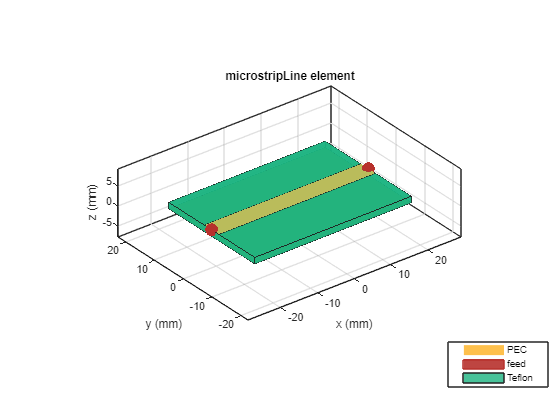

l1 = phaseShift.PortLineLength;
l2 = phaseShift.SectionShape.Length(2);
w = phaseShift.PortLineWidth;
mLine = microstripLine('Width',w, 'Length',2*(l1+w)+l2);
figure; show(mLine);

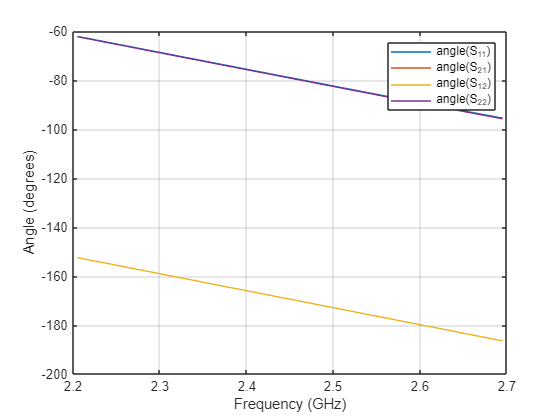

sparamLine=sparameters(mLine, (2205:24.5:2695)*1e6);
figure; rfplot(sparamLine,'angle');

**4.3 **Use the graphical interface to **connect port 3 of the Wilkinson splitter with port 1 of the phase shifter**. 

Save the resulting object to the workspace with the name **pcb**.

pcbcascade(wilkCombiner,phaseShift,'Interactive',true);

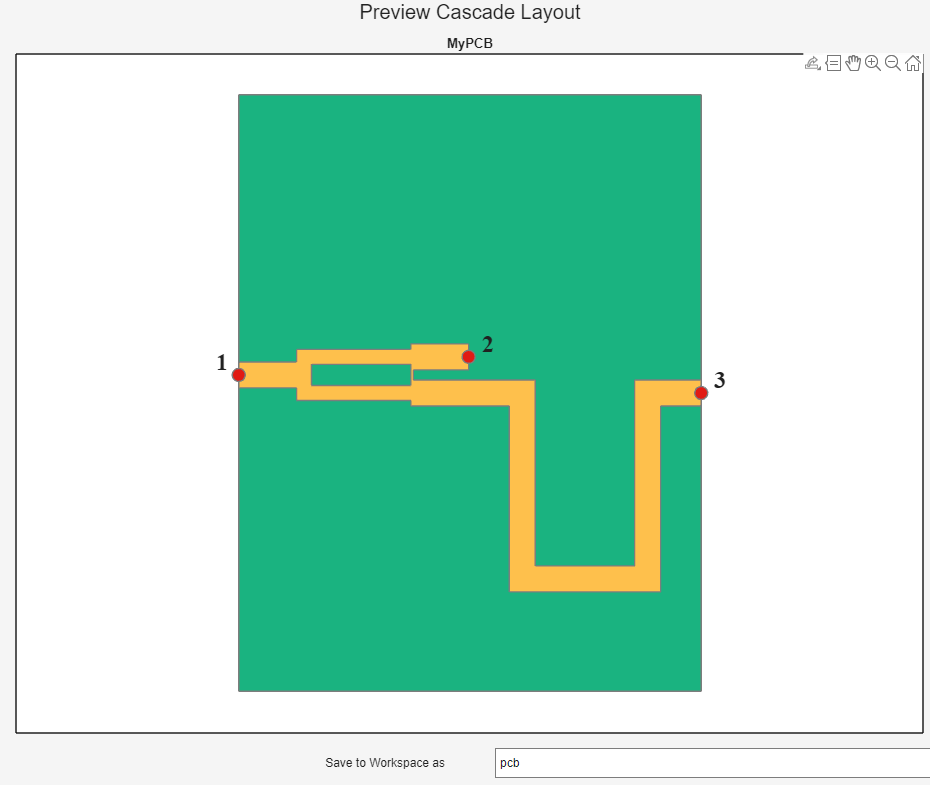

**4.4** Use again the same graphical interface to **connect port 2 of the PCB structure created in the previous step with port 1 of the microstrip line**. 

Save the resulting object to the workspace with the name **pcb**.

pcbcascade(pcb,mLine,'Interactive',true);

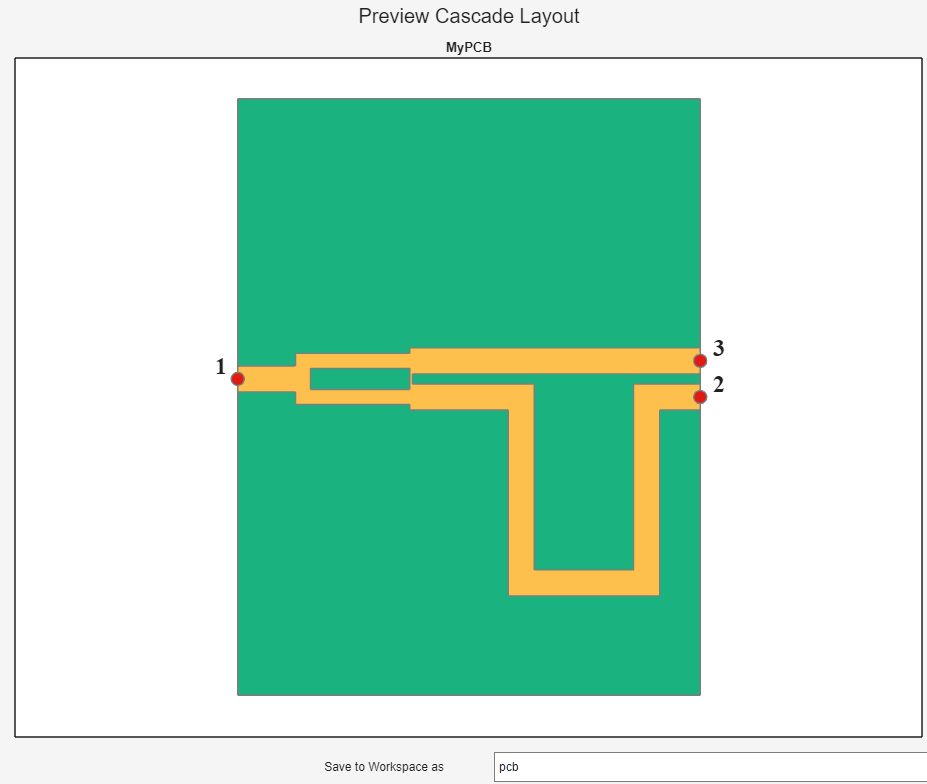

**4.5 **You use EM analysis to compute the S-parameters of the PCB, save them in a Touchstone file. Verify the 90 degrees phase difference along the 2 branches.

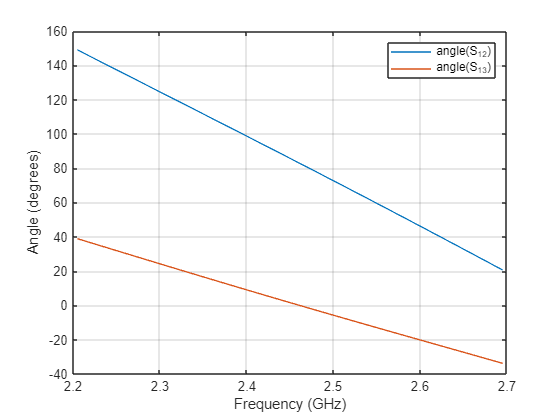

sparamWilkSplitterPhaseShift=sparameters(pcb, (2205:24.5:2695)*1e6);
figure; rfplot(sparamWilkSplitterPhaseShift,1,2,'angle');
hold on; rfplot(sparamWilkSplitterPhaseShift,1,3,'angle');

rfwrite(sparamWilkSplitterPhaseShift,'wilkinsonSplitterPhaseShiftSparams.s3p')

**4.6 **Open the Simulink testbench below, and inside the direct conversion receiver, **open the the **`RF PCB Wilkinson Splitter`** subsystem**. 

open_system('Exercise4_RFReceiverWithPCB.slx')

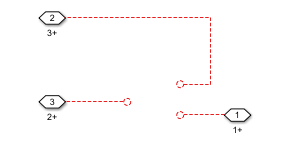

Add an S-parameter block, and specify the Touchstone file `wilkinsonSplitterPhaseShiftSparams.s3p`.

Enable noise generation in the block.

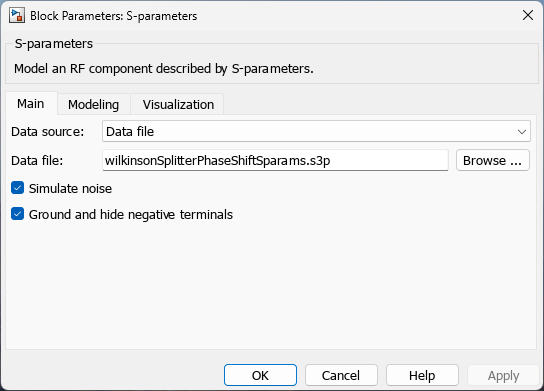

Connect the three port S-parameter block, run the simulation, and verify the ChER to be around 12%.

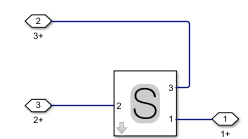

Extra: verify how the additional phase rotation introduced by the combiner / phase offset is accounted for in the baseband receiver and comment about:

- Is the model representative of the actual baseband receiver implementation?

- Would this approach also work for a wideband modulated signal?

**Solution **

Create the PCB integrating the Wilkinson combiner with the phase shift, the microstrip line. Compute the S-parameters and visualize them. Verify phase shifts on both branches as well as the transmission loss.

wilkCombiner=design(wilkinsonSplitter, 2.45e9);
phaseShift = design(phaseShifter, 2.45e9);
l1 = phaseShift.PortLineLength;
l2 = phaseShift.SectionShape.Length(2);
w = phaseShift.PortLineWidth;
mLine = microstripLine('Width',w, 'Length',2*(l1+w)+l2);
wilkSplitterPhaseShift = pcbcascade(wilkCombiner,phaseShift,3,1); 
wilkSplitterPhaseShift = pcbcascade(wilkSplitterPhaseShift,mLine,2,1); 
figure; show(wilkSplitterPhaseShift);
sparamWilkSplitterPhaseShift=sparameters(wilkSplitterPhaseShift, (2205:24.5:2695)*1e6);
figure; rfplot(sparamWilkSplitterPhaseShift,1,2,'angle');
hold on; rfplot(sparamWilkSplitterPhaseShift,1,3,'angle');
figure; rfplot(sparamWilkSplitterPhaseShift,1,2);
rfwrite(sparamWilkSplitterPhaseShift,'wilkinsonSplitterPhaseShiftSparams.s3p')

Open the resulting integrated model:

open_system('Solution4_RFReceiverWithPCB.slx')

The model is not representative of the actual baseband receiver implementation, as the relative phase shift is normally recovered by means of an adaptive clock and phase recovery system.

In this simple model, this approach could be used as the signal phase offset is constant and only dependent on the dispersive components in the chain. In case of a wideband modulated signal though the phase shift would be frequency dependent, and the receiver would require an adaptive equalizer. 

The implemented phase shift of 115 degrees has been determined by inspecting the phase rotation in the budget analysis.

rfBudgetAnalyzer('rfbudget_RFReceiverXdipole.mat') 

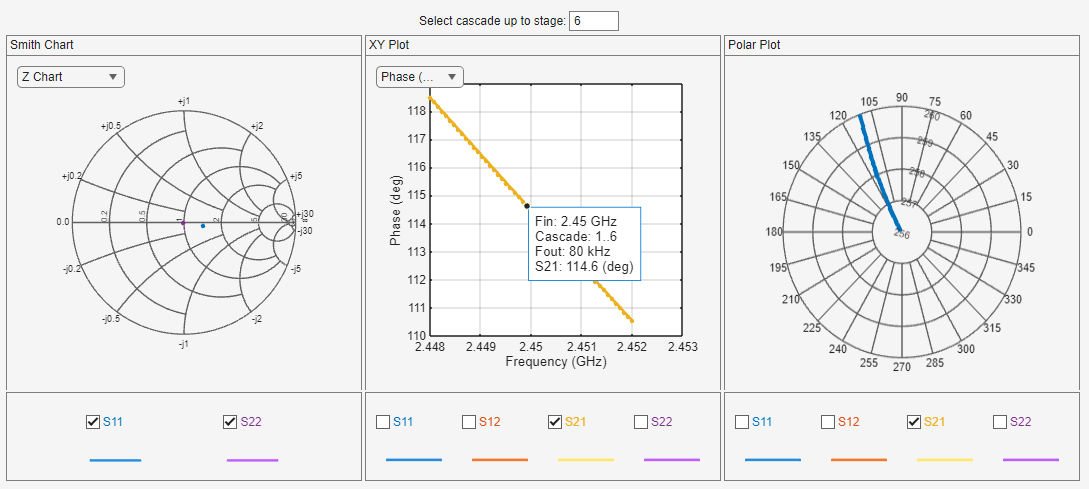

## Conclusion

Following a top-down design methodology, you designed and analyzed the budget of an RF receiver using component specifications. After integrating an antenna, the impact of an interfering signal including polarization mismatch was simulated. A dual polarized antenna and the PCB feed network was integrated to increase modeling fidelity. The design was validated at each stage to confirm that the overall system performance goals were achieved.

*Copyright 2018-2024 The MathWorks, Inc.*